# Inferring a Rat's Location from Hippocampal Place Cell Activity

## (1) Introduction

Sensing our location in space relative to surrounding objects is fundamental to our ability to navigate through the environment. In 1971, O'Keefe and Dostrovsky discovered a type of pyramidal cell in the hippocampus of rats that modulates its activity when the animal enters a particular place in the environment. These cells are called *place cells* and the region of space that elicits a response is the cell's *place field. *The place field is conceptually similar to the idea of a *receptive field* in sensory sysems. 

This script guides you through the analysis of neural activity in hippocampal place cells of a rat while it is moving back and forth along a linear track. This analysis uses real data obtained by Hector Penagos in Matt Wilson's lab at MIT. The data consists of simultaneous recordings of action potentials from 53 cells in hippocampal area CA1 of a rat that is moving freely along a linear track of length 3.6 meters, as shown in the figure below. The goal of the analysis is to recover the rat's spatial trajectory over time, from the neural signals recorded from place cells. 

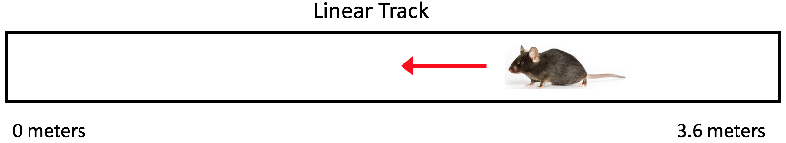

The `PlaceCells `folder contained in the zip file that you downloaded includes code and data files for this activity. Set the Current Folder in MATLAB to the `PlaceCells` folder. To access the data, load the file `DataWilson.mat`:

% load the data into the MATLAB workspace
load DataWilson.mat

## **(2) View the animal's extended trajectory**

The location of the animal on the track was recorded at a frequency of 30 Hz (i.e. one sample every 0.033 sec). We will first view the position of the animal over a long time period of about 14 minutes, spanning several traversals of the track, and then focus on the neural activity measured during one traversal. The vector `AnimalPosition` stores the position of the animal at each moment and `TimestampPosition` stores the actual time of each sample. 

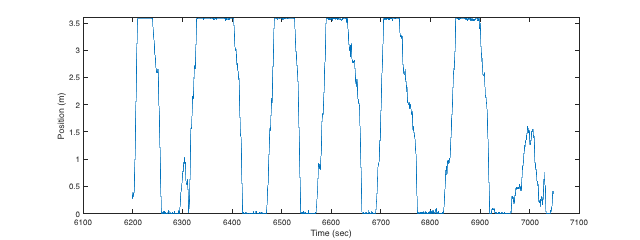

% plot the animal's position over several traversals of the track
figure('Position', [100 100 800 300])
plot(TimestampPosition, AnimalPosition);
xlabel('Time (sec)')
ylabel('Position (m)')
ylim([0 3.6])

Observing this plot, are there places along the track where the animal spends more time?

## **(3) View the place fields for a subset of 12 place cells**

Place cells in the hippocampus are active when the animal is in a particular place in its environment. The place field of a place cell is the region of space over which the cell is active. The neural firing rate of the cell varies within its place field, similar to the receptive field of cells in the visual system. Given that the animal is moving along a linear track in this experiment, the place field is described in one dimension, corresponding to location along the track. 

`PlaceFields` is a 53 x 71 matrix that contains the place fields of 53 place cells. Each row of the matrix stores the place field for a different cell. **The place field is specified by the average firing rate of the cell as a function of the animal's position on the track**. The length of the track is divided into 71 discrete locations (every 0.025 meters over a range of 0.025 to 3.525 meters). These 71 locations are stored in the `PositionBins` vector. Each row of the `PlaceFields` matrix stores the average firing rate in the vicinity of each of these 71 locations, for a single cell. The following code displays the place fields for a subset of 12 place cells.

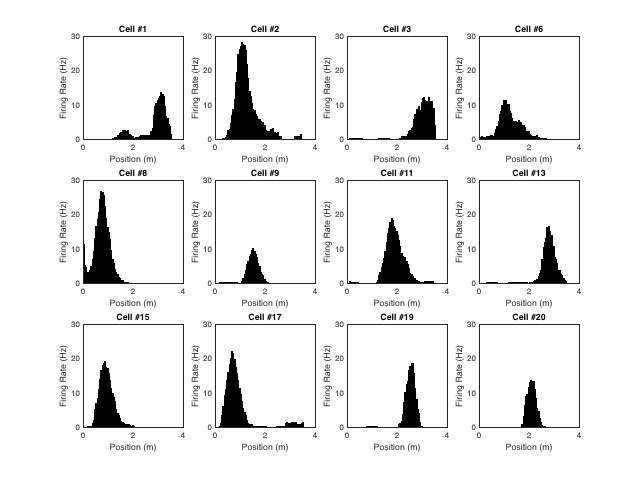

% cell number (row index) for a subset of 12 place cells
cellNum = [1, 2, 3, 6, 8, 9, 11, 13, 15, 17, 19, 20];
figure('Position', [100 100 1000 600])
for i = 1:12
    subplot(3,4,i)
    bar(PositionBins, PlaceFields(cellNum(i), :));
    axis([0 4 0 30])
    xlabel('Position (m)')
    ylabel('Firing Rate (Hz)')
    title(['Cell #' num2str(cellNum(i))])
end

What is the overall shape of these sample place fields? Roughly how wide is a typical place field, in meters? Is the maximum firing rate the same for all 12 place fields?

## **(4) View sample spike trains from a single traversal of the track**

The sequence of action potentials recorded from a neuron in response to a stimulus is referred to as a *neural spike train*. In this part, you will view the neural spike train for four (carefully selected) place cells during a single traversal of the track. `SpikeTimesTrial1` is a cell array of 53 elements, where each location stores a vector of the times at which spikes occurred during a single traversal of the linear track. The data include spike times for three "trials", or three traversals of the linear track, stored in the variables `SpikeTimesTrial1`, `SpikeTimesTrial2`, and `SpikeTimesTrial3`. The variables `Trial1Start` and `Trial1End` specify the start and ending times for Trial 1, and similar variables specify these times for Trials 2 and 3. 

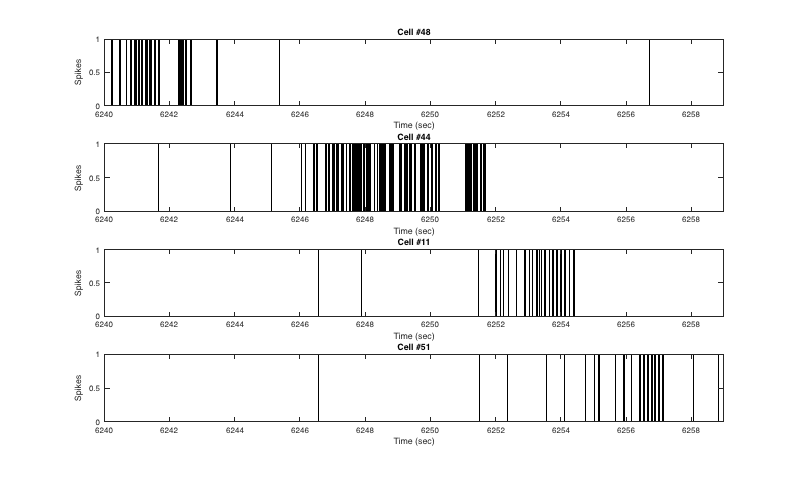

% display the raw neural spike trains recorded from four place cells
% during one traversal of the animal along the linear track
figure('Position', [100 100 1000 600])
cellNum = [48 44 11 51];
for i = 1:4
    subplot(4,1,i)
    spikeTimes = SpikeTimesTrial1{cellNum(i)};
    spikes = ones(length(spikeTimes),1);
    bar(spikeTimes, spikes);
    axis([TrialStart TrialEnd 0 1])
    xlabel('Time (sec)')
    ylabel('Spikes')
    title(['Cell #' num2str(cellNum(i))])
end

## **(5) Decoding the animal's trajectory using a simple winner-take-all strategy**

We have so far seen how place cells can *encode* the position of the animal in the environment through increased spike activity when the animal enters the place fields of these neurons. How can we *decode* this neural activity to recover the trajectory of the animal? If this can be done, it would suggest that place cells adequately encode the position of the animal in space. We begin with the following simple *winner-take-all *decoding strategy:

At each moment: 

(1) determine which place cell has the highest firing rate,

(2) use the preferred location for this place cell as the instantaneous location of the animal.

To apply this strategy, we first need to determine the preferred location for each place cell from its place field:

% determine the index of the preferred location for each place cell 
% from its place field
[maxFiringRate, maxIndex] = max(PlaceFields,[],2);

% convert the indices stored in maxIndex to position on the track
maxPlace = PositionBins(maxIndex);

We can verify the preferred locations stored in `maxPlace` by repeating the display of the 12 place fields shown earlier, with a red line indicating the preferred location based on the maximum firing rate.

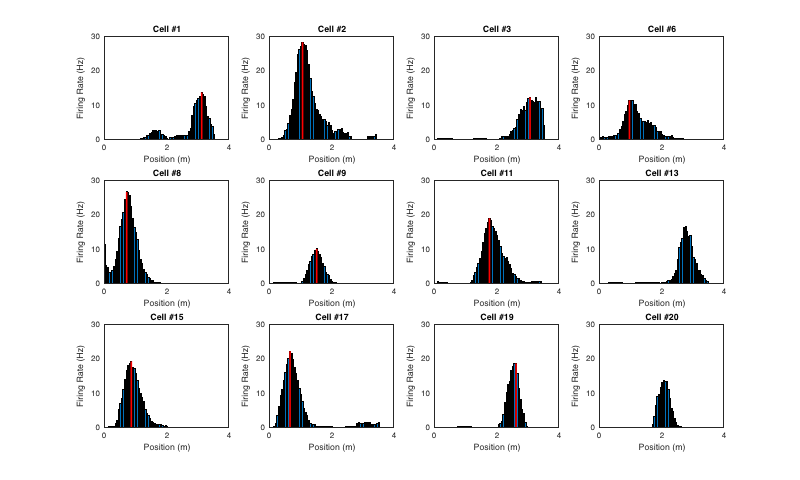

% cell number (row index) for a subset of 12 place cells
cellNum = [1, 2, 3, 6, 8, 9, 11, 13, 15, 17, 19, 20];
figure('Position', [100 100 1000 600])
for i = 1:12
    subplot(3,4,i)
    bar(PositionBins, PlaceFields(cellNum(i), :));
    hold on
    pos = maxPlace(cellNum(i));
    plot([pos pos], [0 maxFiringRate(cellNum(i))], 'r', 'LineWidth', 2);
    axis([0 4 0 30])
    xlabel('Position (m)')
    ylabel('Firing Rate (Hz)')
    title(['Cell #' num2str(cellNum(i))])
end

To determine which place cell has the highest firing rate at each moment, we need to compute the firing rate of every place cell, at each point in time. Firing rate is typically expressed as the number of spikes per second (Hz). The `computeFiringRates` function computes the firing rates by summing the number of spikes generated within a small time window given by the parameter `tau`. 

% compute firing rates for all place cells during Trial 1
tau = 0.25;
firingRatesTrial1 = computeFiringRates(SpikeTimesTrial1, TrialStart, TrialEnd, tau);

We can plot the firing rates for the same four place cells whose spike trains were shown earlier.

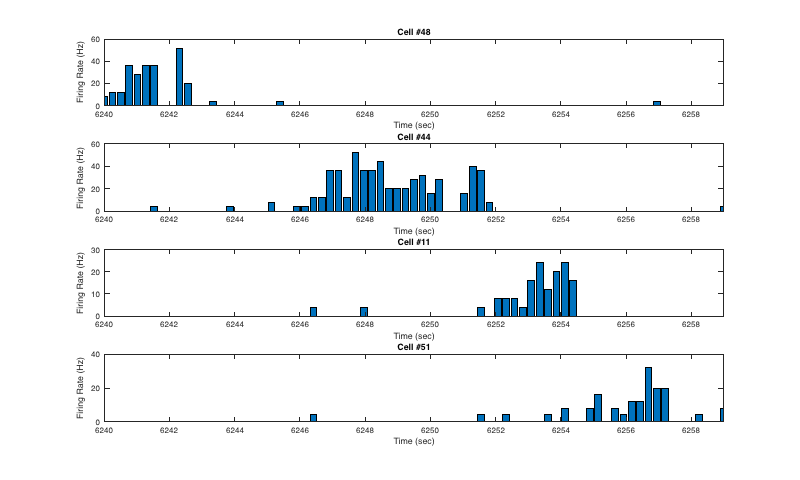

% display the firing rates of four place cells during one traversal 
% of the animal along the linear track
figure('Position', [100 100 1000 600])
cellNum = [48 44 11 51];
for i = 1:4
    subplot(4,1,i)
    rates = firingRatesTrial1(cellNum(i),:);
    times = linspace(TrialStart, TrialEnd, length(rates));
    bar(times, rates);
    xlim([TrialStart TrialEnd]);
    xlabel('Time (sec)')
    ylabel('Firing Rate (Hz)')
    title(['Cell #' num2str(cellNum(i))])
end

Note the difference in range of firing rates for each place cell.

We are now ready to decode the animal's positions along the track, for Trial 1. 

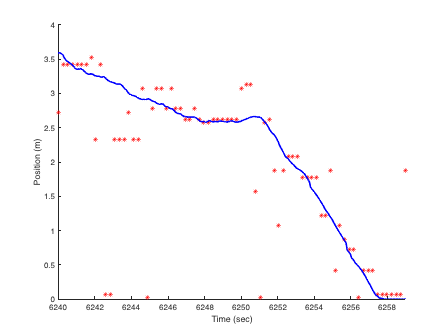

% determine which place cell has the maximum firing rate at each moment, 
% and then determine the preferred location for this place cell
[maxRate, maxIndex] = max(firingRatesTrial1);
posTrial1 = maxPlace(maxIndex);

% display the computed trajectory of the animal for Trial 1
figure
timesTrial1 = linspace(TrialStart, TrialEnd, 75);
scatter(timesTrial1, posTrial1, 'r*')
hold on
plot(TimestampPosition, AnimalPosition, '-b', 'LineWidth', 2);
xlim([TrialStart, TrialEnd])
xlabel('Time (sec)')
ylabel('Position (m)')

In the plot of results, red asterisks indicate the position derived from the model at each moment and the solid blue curve shows the actual trajectory of the rat. There are clearly some errors in the computed trajectory - why might these errors occur?

## **(6) Decoding the animal's trajectory using a maximum likelihood approach**

In this section, we decode the animal's position on the track using *maximum likelihood estimation *(MLE), which computes a location at each moment that maximizes the likelihood of occurrence, given the spiking activity of the place cells that is the observed data. MLE is more complex than the winner-take-all approach, but usually a lot more accurate. 

**Let's assume we want to decode the animal's position based on the spiking activity of the 53 neurons in a time window of length **`tau`** (**$\tau$**). The first step is to count the number of spikes elicited by each of the 53 neurons in the time window of interest.** Let's denote the spike counts for the neurons by $n_1,n_2,\dots,n_{53}$. The animal's position is divided into 71 bins, captured in the variable `PositionBins`. Using the maximum-likelihood estimation strategy, **we compute the probability of the 53 neurons eliciting **$n_1,n_2,\dots,n_{53}$** spikes if the animal was in each of the 71 positions, and find the position that corresponds to the highest probability. **

**Let's break down the process into simpler steps.** First, let's find the probability of neurons eliciting $n_1,n_2,\dots,n_{53}$ spikes if the animal is in position 1 ($x_1$). We call this the likelihood ($\mathcal{L}$) that the animal is in position  $x_1$, and denote it by $\mathcal{L}(x_1|\mathbf{n})$, where $\mathbf{n}$ is shorthand for $n_1,n_2,\dots,n_{53}$. We can write this as follows:


$$\mathcal{L}(x_1|\mathbf{n})= p(n_1,n_2,\dots,n_{53}|x_1)$$
 

If we assume that the neurons are independent, we can find this probability for each neuron independently and multiply the resulting values:


$$\mathcal{L}(x_1|\mathbf{n})= p(n_1|x_1)\times p(n_2|x_1) \times \dots \times p(n_{53}|x_1)$$


Next, **let us assume that each neuron's firing rate has Poisson variability, so that the probability terms can be written in terms of a Poisson probability distribution** as follows:


$$p(n_i|x_1)=\frac{(\tau f_i(x_1))^{n_i}}{n_i!}  \exp{(-\tau f_i(x_1))}$$


In this equation, $\tau$** is the length of the time window in which spikes are counted (in seconds) and **$f_i(x_1)$** is the average firing rate of cell **$i$** at position **$x_1$** (in spikes per second).** The average firing rates can be obtained from the corresponding place fields (stored in the variable `PlaceFields`). The product $\tau f_i(x_i)$ is sometimes referred to as $\lambda$, which characterizes both the mean and variance of a Poisson distribution. The MATLAB function `poisspdf` can be used to implement this function. 

We now have all the ingredients to compute $\mathcal{L}(x_1|\mathbf{n})$ and can do the same for position 2, position 3, and so on, up to position 71, to find the likelihood that the animal is in each position on the track. The last step of the maximum-likelihood estimation is to find the position with the highest likelihood, i.e. the one that corresponds to the largest probability. 

To summarize, we divide the computation into the following four steps:

- discretize the total time of interest into (non-overlapping) bins of duration $\tau$`,`

- count the number of spikes generated by each place cell in each time bin - these are the values $n_1,n_2,\dots,n_{53}$ that will be used for each time bin,

- compute the likelihood across all position bins using the spike count of all the place cells for each time bin,

- for each time bin, find the maximum-likelihood estimate of the animal's position - this is the decoded position.

Steps 1 and 2 can be accomplished with the `computeSpikeCounts` and `computeLikelihood` functions:

% compute the spike counts over windows of size tau, and likelihood across all
% position bins for all of the place cells
tau = 0.25;
spikeCounts = computeSpikeCounts(SpikeTimesTrial1, TrialStart, TrialEnd, tau);
likelihood = computeLikelihood(spikeCounts, PlaceFields, tau);

Let's view the likelihood as a function of position bins for the time bins from 46 to 50:

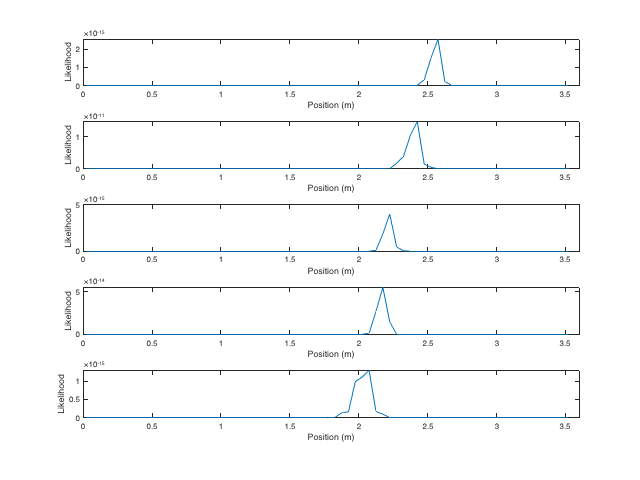

% display the likelihoods for all position bins
timeBins = 46:50;
figure('Position', [100 100 800 600])
for i = 1:5
    subplot(5,1,i)
    plot(PositionBins, likelihood(:, timeBins(i)))
    xlabel('Position (m)');
    ylabel('Likelihood');
    xlim([0 3.6])
end

## Pho Actual Data Analysis

% Actual timesteps if we want those
% timesteps_array{1, 1}
tau = 0.1 % bin size (seconds)

tau =           0.1

% spikeCounts = active_processing.processed_array{1, 1}.all.binned_spike_counts;

% spikeCounts = active_processing.processed_array{1, 1}.by_epoch.track.binned_spike_counts;
% spikeCounts = spikeCounts(plot_outputs.filter_active_units); % 1x68, like it should be



Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).





% likelihood_timestamps = 

## Back to Tutorial

In the following visualization, the maximum likelihood position estimate is displayed as a function ot time (red asterisks), superimposed on the real trajectory of the animal (solid blue curve).

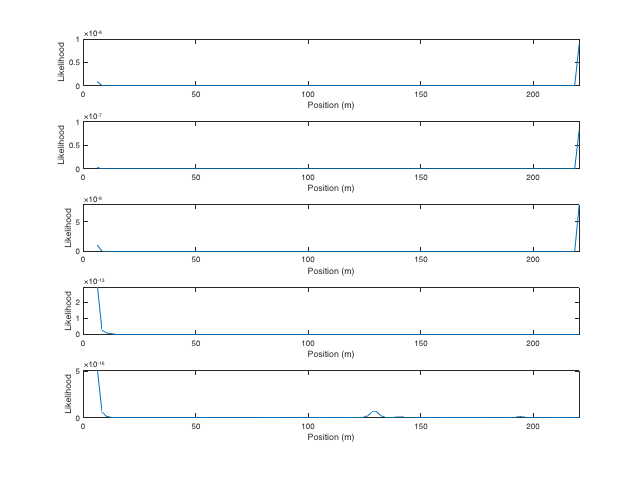

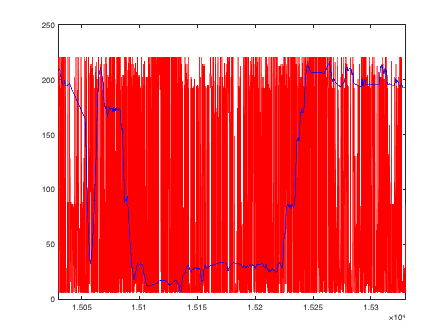

Error using xlim (line 31)
Limits must be a 2-element vector of increasing numeric values.


figure
clf
hold off;
% plot the most likely trajectory
% scatter(activeTimeBins, maxL, 'r', 'MarkerEdgeAlpha',0.4');
plot(activeTimeBins, maxL, 'r');
hold on

% Plot the animal's actual trajectory
plot(t_rel, fileinfo.xyt2(:, 1), 'b', 'LineWidth', 0.5); 
hold off;
xlim([15030 15330]);

% plot(1:length(maxL), maxL, 'r');
xlim([active_processing.behavioral_epochs.start_seconds(2) 0.1 * active_processing.behavioral_epochs.end_seconds(2)]); % [15141, 15162] are good
% xlim([active_processing.behavioral_epochs.start_seconds(2) active_processing.behavioral_epochs.end_seconds(2)]);

% plot(maxL, 'r*');

% plot(windows, maxL, 'r*');
% hold on
% plot(TimestampPosition, AnimalPosition, '-b', 'LineWidth', 2);
% xlim([TrialStart TrialEnd])
% hold off
% xlabel('Position (m)');
% ylabel('Time (sec)');

This analysis can be repeated using time windows of 0.025 and 1.0 seconds. What are the advantages and disadvantages of choosing short and long time windows? Which of the three time windows works best for decoding?

% repeat the analysis with a smaller time window of 0.025 seconds
tau = 0.025;
spikeCounts = computeSpikeCounts(SpikeTimesTrial1, TrialStart, TrialEnd, tau);
likelihood = computeLikelihood(spikeCounts, PlaceFields, tau);
[~, index] = max(likelihood, [], 1);
maxL = PositionBins(index);
nTimeBins = ceil((TrialEnd-TrialStart)/tau);
windows = linspace(TrialStart, TrialEnd, nTimeBins-1);

figure
plot(windows, maxL, 'r*');
hold on
plot(TimestampPosition, AnimalPosition, '-b', 'LineWidth', 2);
xlim([TrialStart TrialEnd])
hold off
xlabel('Position (m)');
ylabel('Time (sec)');

Repeating the analysis with a 1-second time window:

% repeat the analysis with a larger time window of 1.0 seconds
tau = 1.0;
spikeCounts = computeSpikeCounts(SpikeTimesTrial1, TrialStart, TrialEnd, tau);
likelihood = computeLikelihood(spikeCounts, PlaceFields, tau);
[~, index] = max(likelihood, [], 1);
maxL = PositionBins(index);
nTimeBins = ceil((TrialEnd-TrialStart)/tau);
windows = linspace(TrialStart, TrialEnd, nTimeBins-1);

figure
plot(windows, maxL, 'r*');
hold on
plot(TimestampPosition, AnimalPosition, '-b', 'LineWidth', 2);
xlim([TrialStart TrialEnd])
hold off
xlabel('Position (m)');
ylabel('Time (sec)');

Repeating this analysis for Trial 2:

tau = 0.025;
spikeCounts = computeSpikeCounts(SpikeTimesTrial2, Trial2Start, Trial2End, tau);
likelihood = computeLikelihood(spikeCounts, PlaceFields, tau);
[~, index] = max(likelihood, [], 1);
maxL = PositionBins(index);
nTimeBins = ceil((Trial2End-Trial2Start)/tau);
windows = linspace(Trial2Start, Trial2End, nTimeBins-1);

figure
plot(windows, maxL, 'r*');
hold on
plot(TimestampPosition, AnimalPosition, '-b', 'LineWidth', 2);
xlim([Trial2Start Trial2End])
hold off
xlabel('Position (m)');
ylabel('Time (sec)');

Repeating this analysis for Trial 3:

tau = 0.025;
spikeCounts = computeSpikeCounts(SpikeTimesTrial3, Trial3Start, Trial3End, tau);
likelihood = computeLikelihood(spikeCounts, PlaceFields, tau);
[~, index] = max(likelihood, [], 1);
maxL = PositionBins(index);
nTimeBins = ceil((Trial3End-Trial3Start)/tau);
windows = linspace(Trial3Start, Trial3End, nTimeBins-1);

figure
plot(windows, maxL, 'r*');
hold on
plot(TimestampPosition, AnimalPosition, '-b', 'LineWidth', 2);
xlim([Trial3Start Trial3End])
hold off
xlabel('Position (m)');
ylabel('Time (sec)');

For each trial, during which periods of time does the recovery of the spatial trajactory based on the maximum likelihood estimate work best? Compare times when the animal is moving at low and high velocities, and when there are changes in the movement direction (this information can be extracted graphically from the trajectory plots).

## **(7) References**

O'Keefe, J. & Dostrovsky, J. (1971) The hippocampus as a spatial map: Preliminary evidence from unit activity in the freely-moving rat. *Brain Research* 34: 573-590. [PDF accesible here](https://ac.els-cdn.com/0006899371903581/1-s2.0-0006899371903581-main.pdf?_tid=ad8a81f2-84fb-4724-95ec-133590ec315a&acdnat=1543948214_fe635a1bbadaf4d89dff5344f2ca6b6f)

Zhang, K., Ginzburg, I., McNaughton, B. L. & Sejnowski, T. (1988) Interpreting neural population activity by reconstruction: Unified framework with application to hippocampal place cells. *J. Neurophysiol.* 79: 1017-1044. [PDF freely accesible here](https://www.physiology.org/doi/pdf/10.1152/jn.1998.79.2.1017)